BC = 5

BC = 5

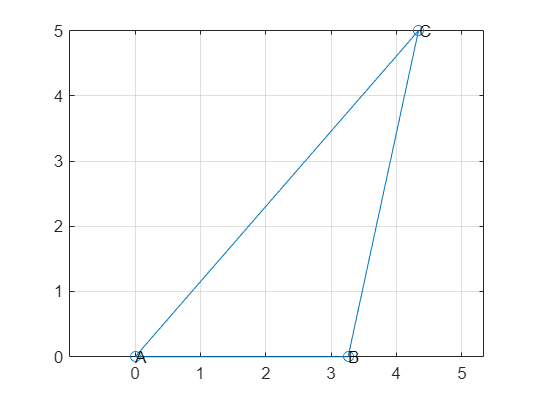

A = 34

B = 59.0000

C = 87

AB = 3.2619

BC = 5

CA = 4.3405


[A B C AB BC CA] = solveTriangle(34, 59, nan, nan, 5, nan)

function [A,B,C,AB,BC,CA] = solveTriangle(A,B,C,AB,BC,CA)
    % Convert all angles to radians for computation
    A = deg2rad(A);
    B = deg2rad(B);
    C = deg2rad(C);

    for i = 1:3

    % Solve for unknown sides
    if isnan(CA)
        if ~isnan(B) && ~isnan(AB) && ~isnan(BC)
            CA = sqrt(AB^2 + BC^2 - 2*AB*BC*cos(B));  % Cosine Rule
        else
            CA = sqrt(AB^2 + BC^2); % Pythagoras
        end
    elseif isnan(AB)
        if ~isnan(A) && ~isnan(BC) && ~isnan(CA)
            AB = sqrt(BC^2 + CA^2 - 2*BC*CA*cos(A));  % Cosine Rule
        else
            AB = sqrt(CA^2 - BC^2); % Pythagoras
        end
    elseif isnan(BC)
        if ~isnan(C) && ~isnan(AB) && ~isnan(CA)
            BC = sqrt(AB^2 + CA^2 - 2*AB*CA*cos(C));  % Cosine Rule
        else
            BC = sqrt(CA^2 - AB^2); % Pythagoras
        end
    end

    % Solve for the remaining angles using the Sine Rule
    if isnan(A)
        A = asin(sin(B) * (AB / BC));
    elseif isnan(B)
        B = asin(sin(A) * (BC / AB));
    elseif isnan(C)
        C = asin(sin(A) * (CA / AB));
    end

    % Solve for unknown angles
    if isnan(A)
        A = pi - B - C;  % Calculate remaining angle
    elseif isnan(B)
        B = pi - A - C;  % Calculate remaining angle
    elseif isnan(C)
        C = pi - A - B;  % Calculate remaining angle
    end

    if ~isnan(A) && ~isnan(AB)
        % A and AB are known
        if ~isnan(B)
            % B is known, calculate BC
            BC = AB * sin(B) / sin(A)
        elseif ~isnan(C)
            % C is known, calculate CA
            CA = AB * sin(C) / sin(A);
        elseif ~isnan(BC)
            % BC is known, calculate B
            B = asin(BC * sin(A) / AB);
        elseif ~isnan(CA)
            % CA is known, calculate C
            C = asin(CA * sin(A) / AB);
        end
    elseif ~isnan(B) && ~isnan(BC)
        % B and BC are known
        if ~isnan(A)
            % A is known, calculate AB
            AB = BC * sin(A) / sin(B);
        elseif ~isnan(C)
            % C is known, calculate CA
            CA = BC * sin(C) / sin(B);
        elseif ~isnan(AB)
            % AB is known, calculate A
            A = asin(AB * sin(B) / BC);
        elseif ~isnan(CA)
            % CA is known, calculate C
            C = asin(CA * sin(B) / BC);
        end
    elseif ~isnan(C) && ~isnan(CA)
        % C and CA are known
        if ~isnan(A)
            % A is known, calculate AB
            AB = CA * sin(A) / sin(C);
        elseif ~isnan(B)
            % B is known, calculate BC
            BC = CA * sin(B) / sin(C);
        elseif ~isnan(AB)
            % AB is known, calculate A
            A = asin(AB * sin(C) / CA);
        elseif ~isnan(BC)
            % BC is known, calculate B
            B = asin(BC * sin(C) / CA);
        end
    end

    end

    

    % Convert angles back to degrees for output
    A = rad2deg(A);
    B = rad2deg(B);
    C = rad2deg(C);
    
    % Plot the triangle
    plot([0 AB CA 0], [0 0 BC 0], '-o');
    text(0, 0, 'A');
    text(AB, 0, 'B');
    text(CA, BC, 'C');


    axis equal;
    grid on;
end
